clearvars; close all; clc;

## Automated phenotypic analysis pipeline for HD-MEA recordings. Analyzes human iPSC-derived excitatory neuronal networks (Ngn2) to compare a healthy Control vs. a Dup15q pathological model.

**Extracted Biomarkers:**

- Macro-Dynamics: Mean Firing Rate (MFR), Network Burst Rate (NBR)

- Burst Morphology: Burst Duration, Spikes per Burst, Intra-Burst FR

- Synchrony: Percentage of Spikes During Network Bursts

- Micro-Architecture: Burst Fragmentation (Peak-and-Valley IFR method)

**Dependencies:**

- MATLAB Signal Processing Toolbox (for 'findpeaks')

- Input Data: 'peak_train' and 'NetBurst' .mat files

Author: Lorenzo Porcu 

Date: November 2026 

## 1. CONFIGURATION & EXPERIMENTAL DESIGN

fs = 10000;                     % Sampling frequency (Hz)
recDurationSec = 600;           % Recording duration (s)
minActiveElectrodeFR = 0.1;     % Minimum firing rate for an active electrode (Hz)
baseDir = fullfile(pwd, 'data/MEA_data');

% An electrode is classified as active when its mean firing rate meets this threshold.
% With the current 10-minute recording duration, 0.1 Hz corresponds to 60 spikes.

% Define Groups
ctrl.name = 'Control';
ctrl.path = fullfile(baseDir, 'Controllo');
ctrl.wells = {'Well 11', 'Well 17', 'Well 23'};
ctrl.ptrain = {'ptrain_Control00_Well11', 'ptrain_Control00_Well17', 'ptrain_Control00_Well23'};

patho.name = 'Dup15q';
patho.path = fullfile(baseDir, 'Linea2');
patho.wells = {'Well 8', 'Well 9', 'Well 14'};
patho.ptrain = {'ptrain_Group02_Well8', 'ptrain_Group02_Well9', 'ptrain_Group02_Well14'};

## 2. DATA INGESTION and ACTIVE ELECTRODES DETECTION

fprintf('Loading data and extracting scientific biomarkers...\n');

Loading data and extracting scientific biomarkers...



% Load Data
[ctrl.spikes, ctrl.bursts]   = loadGroupData(ctrl, fs);
[patho.spikes, patho.bursts] = loadGroupData(patho, fs);

% Extract Biomarkers
ctrl.metrics  = extractBiomarkers(ctrl.spikes, ctrl.bursts, fs, recDurationSec, minActiveElectrodeFR);
patho.metrics = extractBiomarkers(patho.spikes, patho.bursts, fs, recDurationSec, minActiveElectrodeFR);

% Report the number of active electrodes detected in each well.
fprintf('\nActive-electrode summary (threshold >= %.2f Hz):\n', minActiveElectrodeFR);


Active-electrode summary (threshold >= 0.10 Hz):


printActiveElectrodeSummary(ctrl);


Control
  Well 11: 12/12 active electrodes
  Well 17: 12/12 active electrodes
  Well 23: 12/12 active electrodes


printActiveElectrodeSummary(patho);


Dup15q
  Well 8: 6/12 active electrodes
  Well 9: 12/12 active electrodes
  Well 14: 1/1 active electrodes


## 3. FEATURE EXTRACTION & VISUALIZATION 

The following dashboard provides a quantitative overview of neuronal network activity by comparing Control and Dup15q cultures across six electrophysiological biomarkers.

The selected metrics describe complementary aspects of network activity:

- **Mean Firing Rate** (MFR): quantifies the average spontaneous firing activity of active electrodes, providing an indication of overall neuronal activity.

- **Network Burst Rate** (NBR): measures how frequently coordinated network-wide bursting events occur.

- **Burst Duration**: describes the temporal extent of network bursting events.

- **Spikes per Network Burst**: quantifies the number of spikes recruited during each network burst, providing information about event intensity.

- **Intra-Burst Firing Rate**: measures the overall population firing rate during network bursts, characterizing the intensity of neuronal activity within these events.

- **Percentage of Spikes During Network Bursts**: estimates the proportion of total recorded spikes occurring during network bursts, indicating how much neuronal activity is associated with these events.

Together, these complementary biomarkers provide a broader characterization of spontaneous neuronal network activity, allowing differences in baseline firing, burst occurrence, temporal organization, and population recruitment to be explored between experimental groups.

fprintf('Generating Phenotypic Dashboard...\n');

Generating Phenotypic Dashboard...


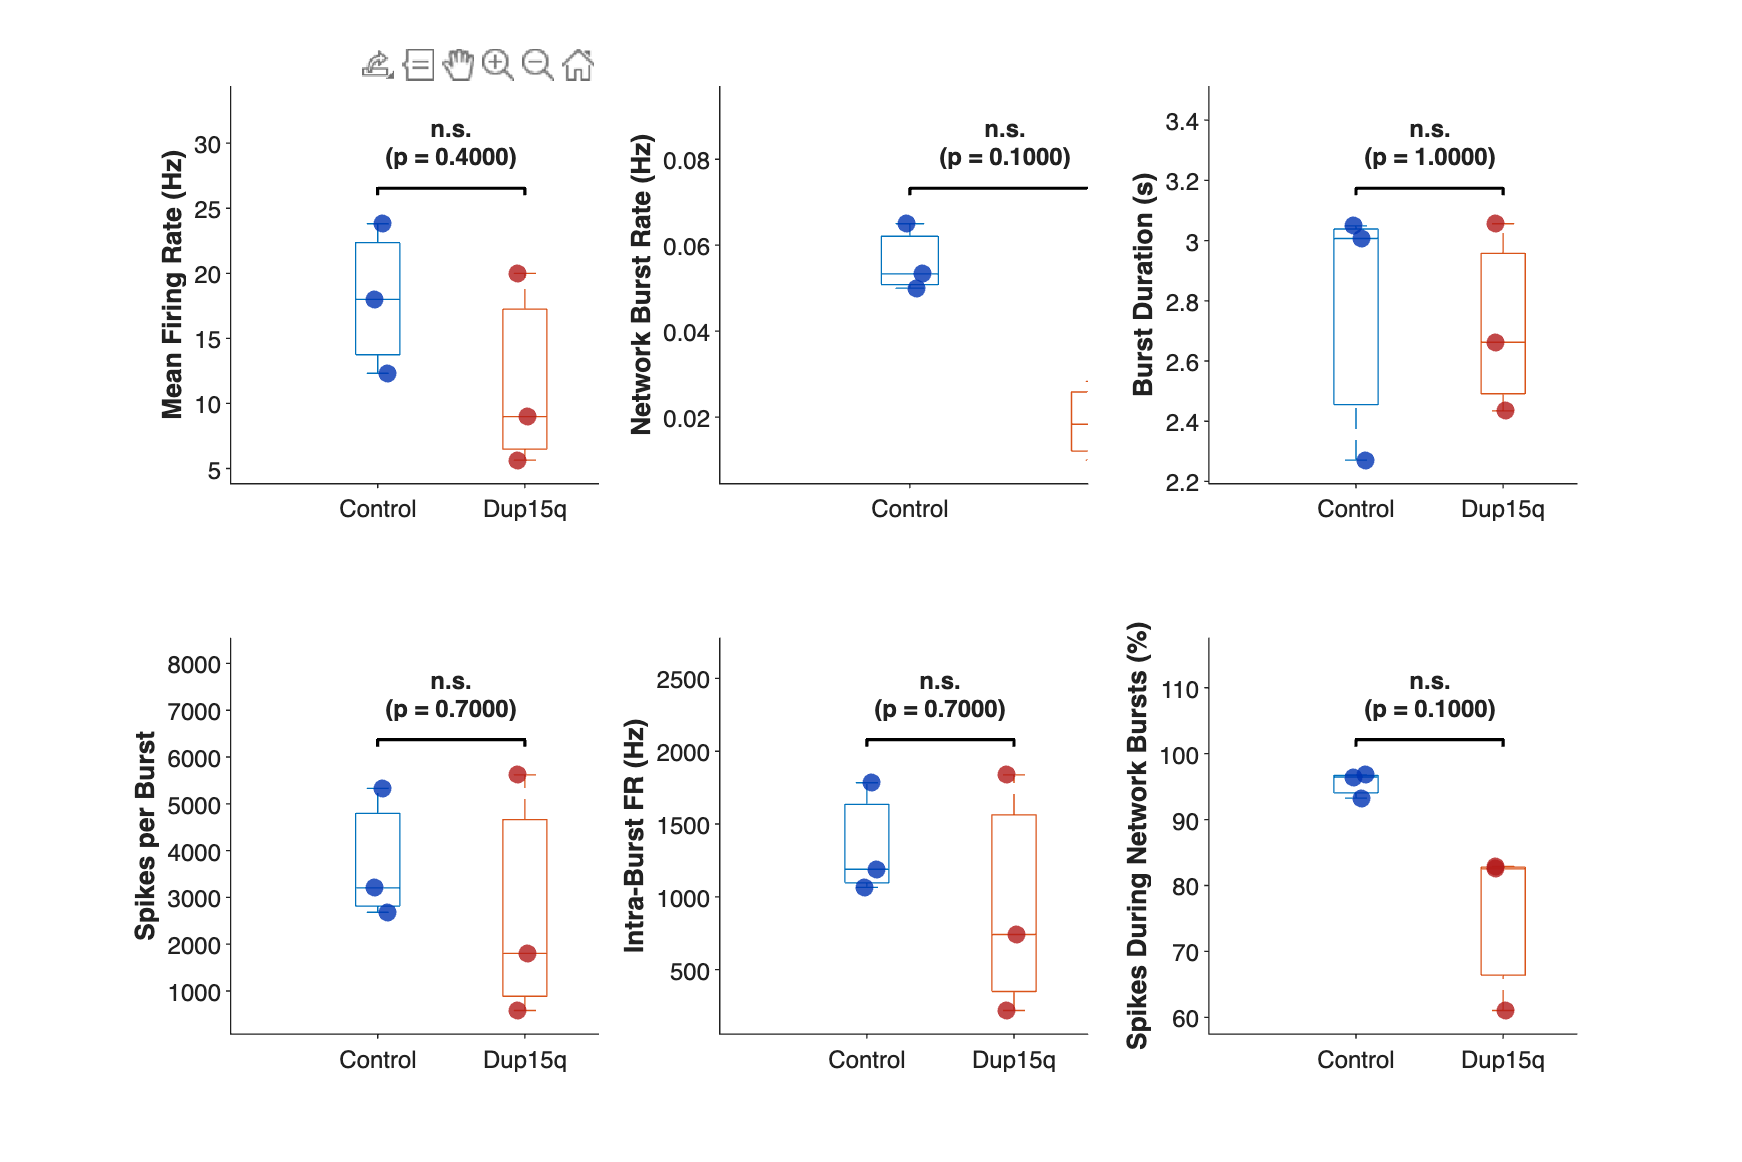


% Create a single dashboard figure for all key metrics
figure('Name', 'Phenotypic Screening Dashboard', 'Color', 'w', 'Position', [100, 100, 1200, 800]);

% Plot 1: Mean Firing Rate
subplot(2,3,1);
compareAndPlot(ctrl.metrics.mfr, patho.metrics.mfr, 'Mean Firing Rate (Hz)', ctrl.name, patho.name);

% Plot 2: Network Burst Rate
subplot(2,3,2);
compareAndPlot(ctrl.metrics.nbr, patho.metrics.nbr, 'Network Burst Rate (Hz)', ctrl.name, patho.name);

% Plot 3: Burst Duration
subplot(2,3,3);
compareAndPlot(ctrl.metrics.burstDur, patho.metrics.burstDur, 'Burst Duration (s)', ctrl.name, patho.name);

% Plot 4: Spikes per Network Burst
subplot(2,3,4);
compareAndPlot(ctrl.metrics.spikesPerBurst, patho.metrics.spikesPerBurst, 'Spikes per Burst', ctrl.name, patho.name);

% Plot 5: Intra-Burst Firing Rate
subplot(2,3,5);
compareAndPlot(ctrl.metrics.intraFR, patho.metrics.intraFR, 'Intra-Burst FR (Hz)', ctrl.name, patho.name);

% Plot 6: Percentage of Spikes Occurring During Network Bursts
subplot(2,3,6);
compareAndPlot(ctrl.metrics.spikesInNetworkBurstsPct, patho.metrics.spikesInNetworkBurstsPct, ...

    'Spikes During Network Bursts (%)', ctrl.name, patho.name);

Generating and saving Raster & IFR visualizations for all wells...


#### STATISTICAL NOTE & METHODOLOGICAL JUSTIFICATION

The two groups are compared at the well level using a two-sided Mann-Whitney U test (Wilcoxon rank-sum; MATLAB function ranksum). A rank-based non-parametric test is used because only three wells per group are available, so distributional assumptions such as normality cannot be assessed reliably. Each well is treated as an independent unit. Results are exploratory: this small sample limits statistical power and the resolution of attainable p-values. No multiple-comparison correction is applied to the six exploratory metrics.

#### KEY OBSERVATIONS & EFFECT SIZE

With N = 3 per group, the total number of rank permutations is nchoosek(6,3) = 20. Therefore, the minimum mathematically achievable p-value for a two-tailed test is exactly p = 2/20 = 0.1000.  Achieving p = 0.1000 on these metrics represents COMPLETE RANK SEPARATION between Control and Dup15q wells (maximum observable effect size for this N). 

#### Interpretation: 

Overall, while global activity metrics (Mean Firing Rate and Network Burst Rate) show overlapping distributions, the primary phenotypic dashboard reveals crucial biological differences within the burst events themselves. Specifically, metrics characterizing intra-burst activity—such as Intra-Burst Firing Rate and the Percentage of Spikes During Network Bursts—yielded a p-value of 0.1000. Given the small sample size of three wells per group, p=0.1000p=0.1000represents the absolute mathematical minimum achievable for a two-sided non-parametric test, indicating a **complete rank separation** between the conditions.

Rather than indicating a failed experiment, this result provides a critical insight: the baseline macro-architecture of the network is largely preserved, but the electrophysiological signature of the Dup15q mutation profoundly alters how spikes are organized *inside* the burst window. Because this disruption is hidden within the micro-dynamics of the signal, we must move beyond global macroscopic averages and examine the internal temporal structure of individual events. Specifically, we need to analyze **burst fragmentation**—investigating whether pathological bursts fracture into smaller, stuttering sub-events—to properly identify and quantify the disease phenotype.

## 4. MACRO & MICRO ARCHITECTURE: OVERLAID RASTER AND IFR (SIDE-BY-SIDE)

To bridge the gap between global averages and internal burst dynamics, we developed a dual-axis visualization that overlays single-electrode raster plots with the population Instantaneous Firing Rate (IFR).

By plotting individual spike events (left axis) alongside the smoothed population firing rate (right axis, 20 ms bin width) and shading the detected network burst boundaries, this tool allows for a direct, side-by-side micro-architectural comparison between Control and Dup15q wells.

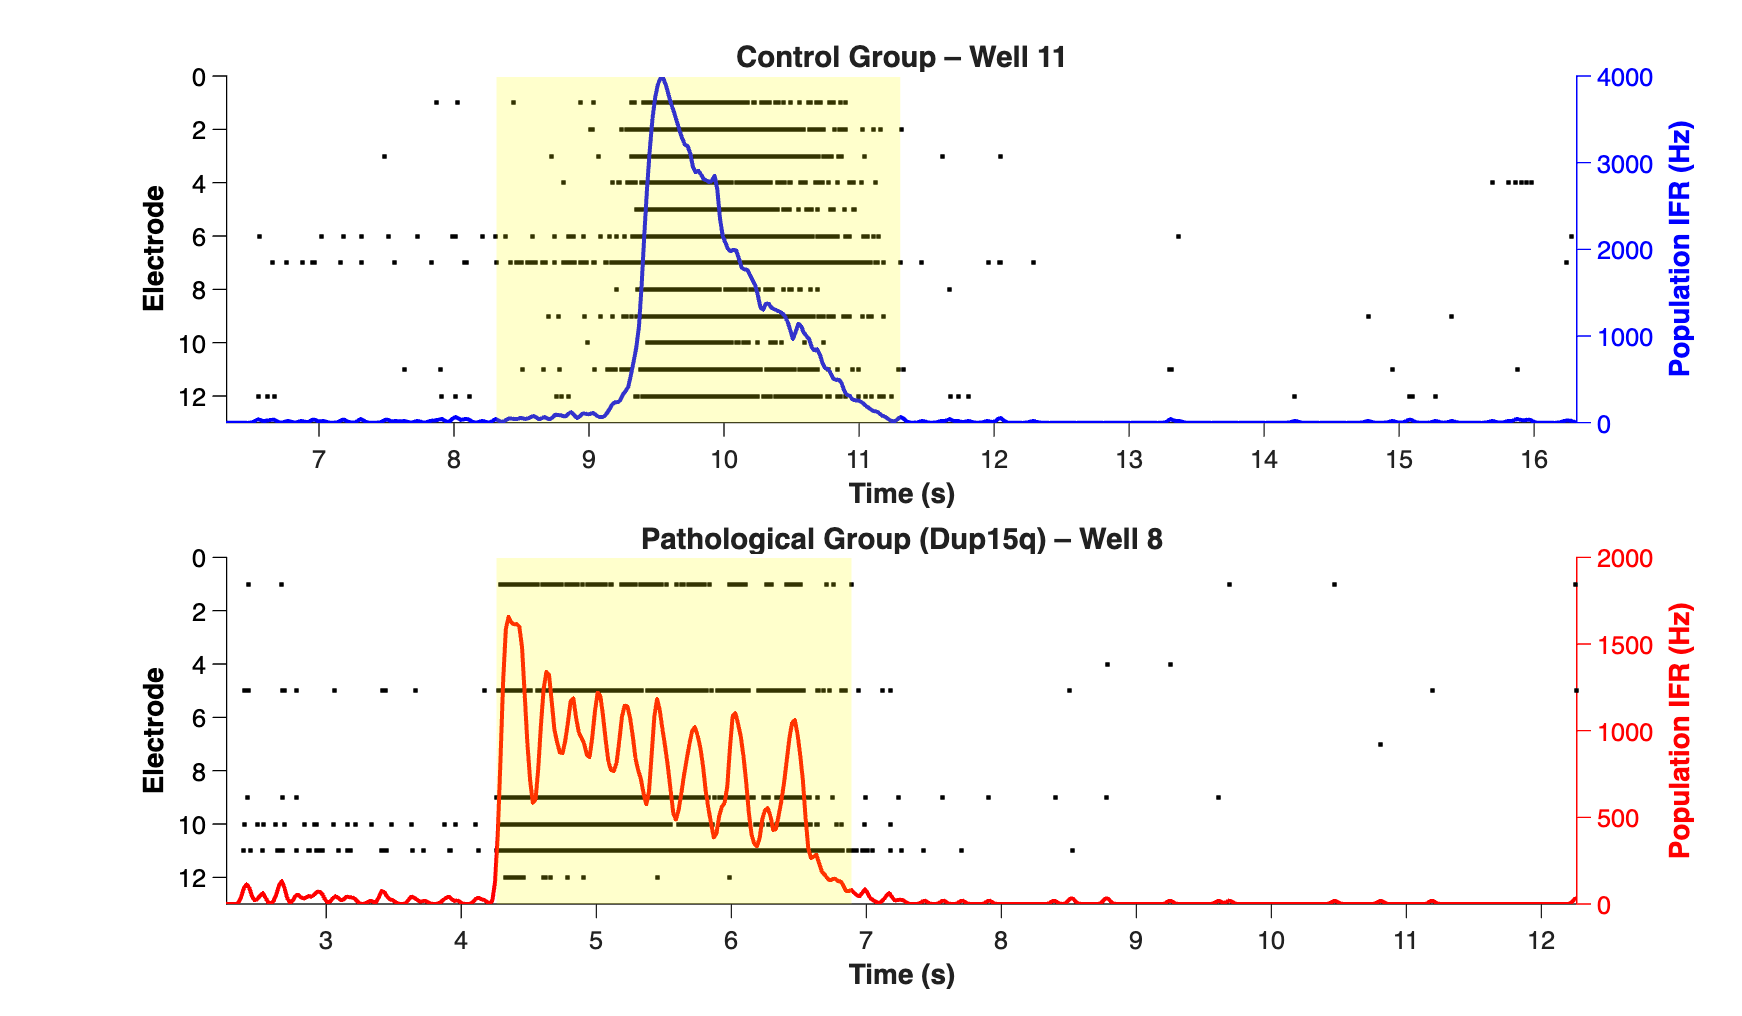

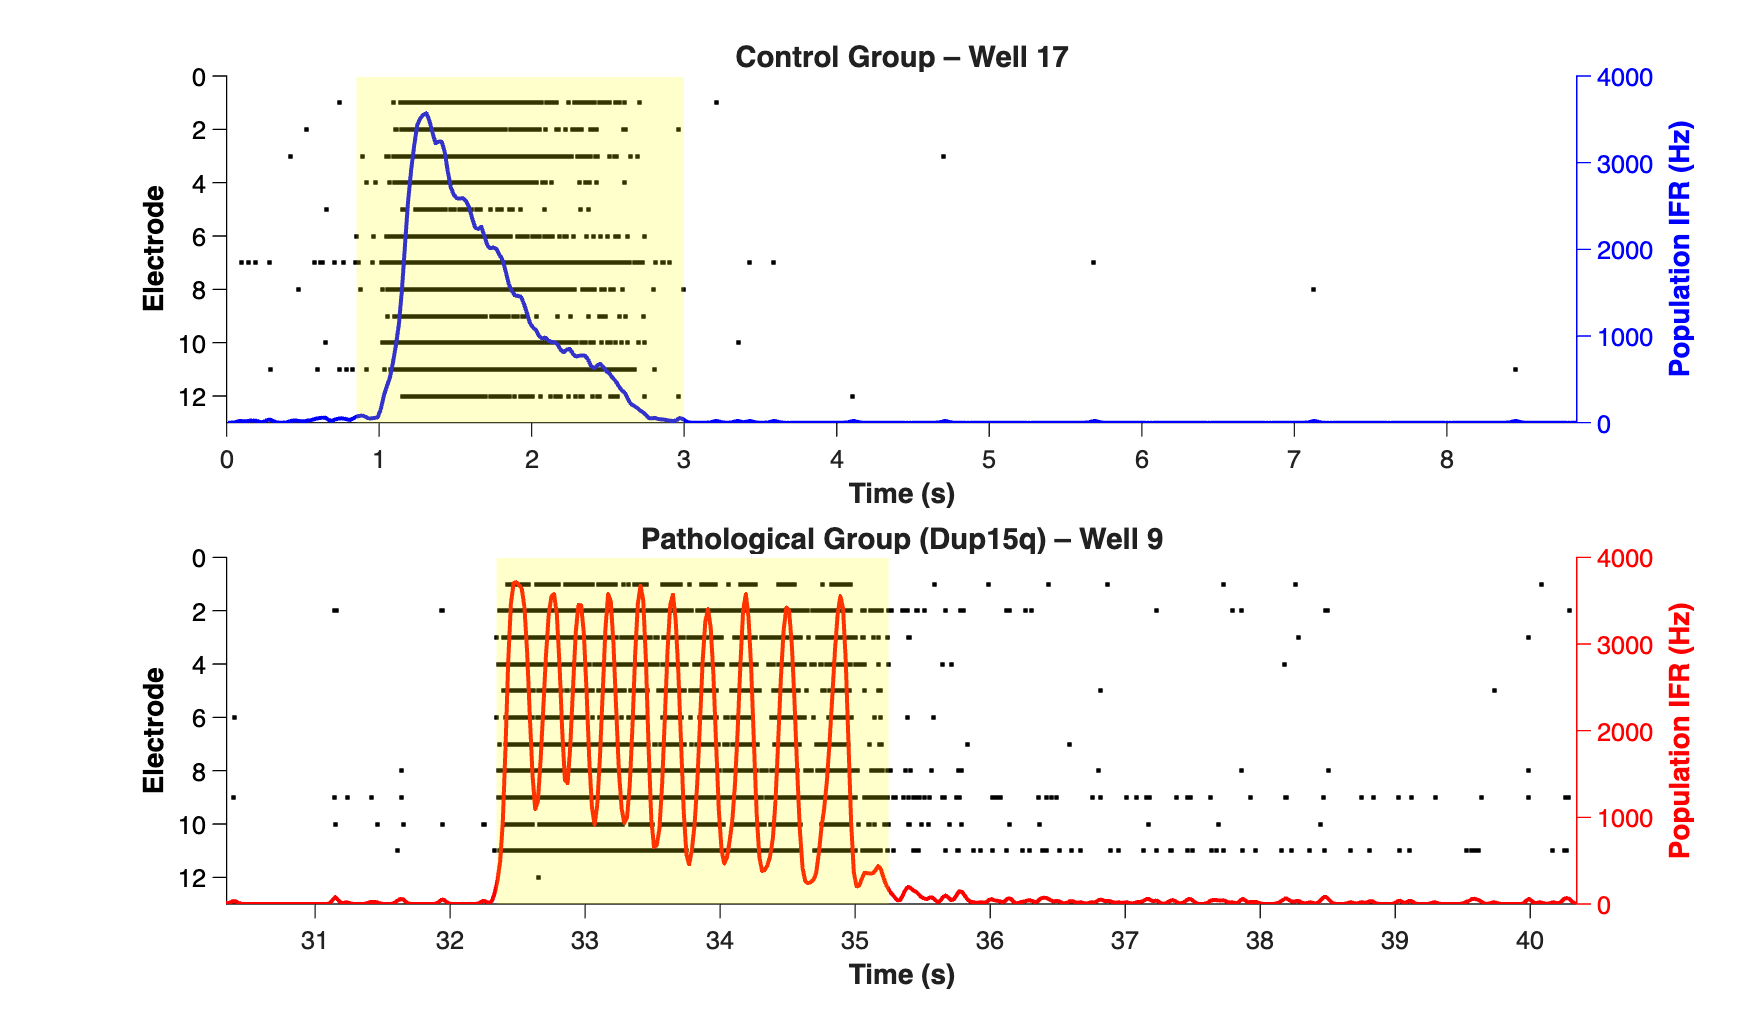

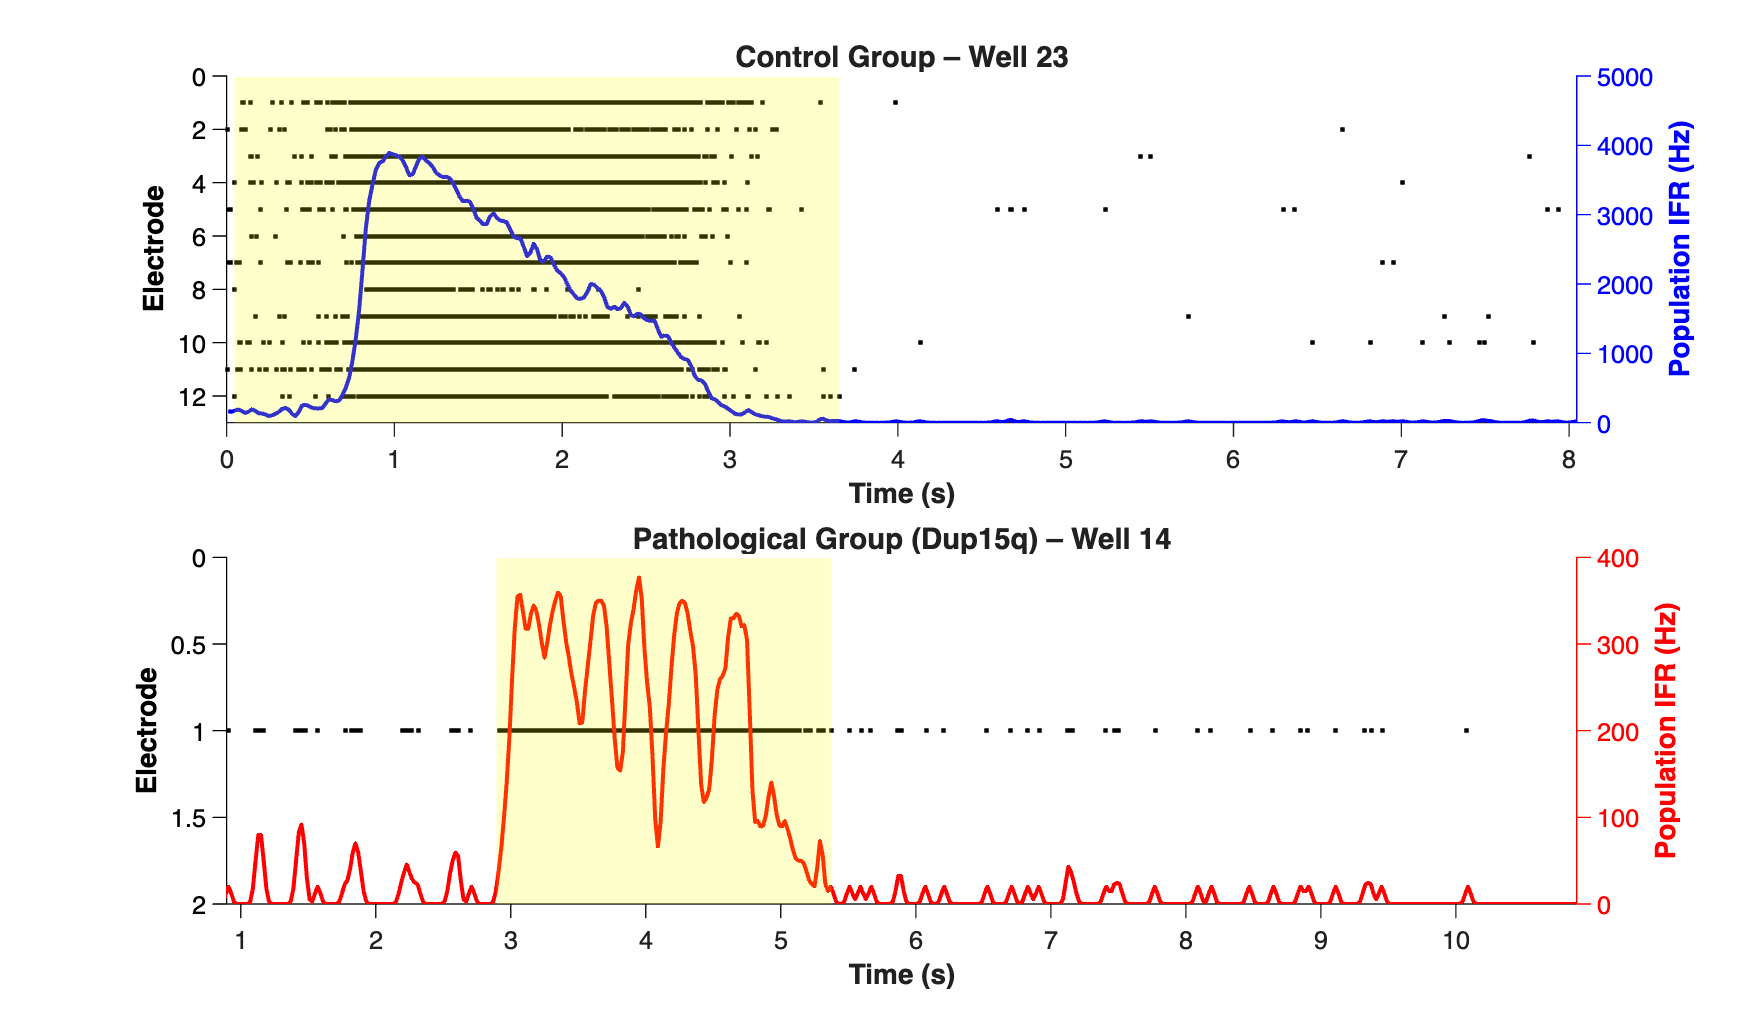


% Automates the creation and saving of the Raster and IFR overlay visualizations 
% for all well pairs (Control vs Dup15q).

fprintf('Generating and saving Raster & IFR visualizations for all wells...\n');

% Parameters for Raster and IFR
binSizeSecRaster = 0.020;   % 20 ms bin resolution
smoothWinRaster  = 5;       % Gaussian smoothing window

% Create the 'images' directory if it does not already exist
if ~exist('images', 'dir')
    mkdir('images');
end

% Determine the number of wells to iterate through
nWells = min(length(ctrl.wells), length(patho.wells));

for w = 1:nWells
    % --- OVERLAID RASTER & IFR (SUBPLOTS) ---
    figRaster = figure('Name', sprintf('Comparative Network Burst Architecture - Pair %d', w), ...
                 'Color', 'w', 'Position', [100, 100, 1200, 700]);
    
    % Subplot 1: Control Well
    subplot(2, 1, 1);
    plotSubplotRasterIFR(ctrl.spikes{w}, ctrl.bursts{w}, fs, ...
        sprintf('Control Group – %s', ctrl.wells{w}), 'b', binSizeSecRaster, smoothWinRaster);
    
    % Subplot 2: Pathological Well
    subplot(2, 1, 2);
    plotSubplotRasterIFR(patho.spikes{w}, patho.bursts{w}, fs, ...
        sprintf('Pathological Group (Dup15q) – %s', patho.wells{w}), 'r', binSizeSecRaster, smoothWinRaster);

    
    % Save the entire figure canvas automatically

Successfully saved 3 Raster/IFR pairs in the "images" folder.


    fileNameRaster = sprintf('images/raster_ifr_overlay_pair_%d.png', w);
    exportgraphics(figRaster, fileNameRaster, 'Resolution', 300);

Successfully saved 3 Raster/IFR pairs and burst details in the "images" folder.


end

Visualization complete for Well 17 vs Well 9.



fprintf('Successfully saved %d Raster/IFR pairs in the "images" folder.\n', nWells);

fprintf('Successfully saved %d Raster/IFR pairs and burst details in the "images" folder.\n', nWells);
fprintf('Visualization complete for %s vs %s.\n', ctrl.wells{ctrlIdx}, patho.wells{pathoIdx});

**Interpretation:**

Zooming in on individual network events reveals a clear structural contrast: while healthy Control networks discharge in a smooth, cohesive firing wave with a single main peak, the Dup15q pathological networks display rapid intra-burst oscillations, dips, and secondary peaks. This visual stuttering provides direct evidence of **burst fragmentation**, confirming that the disease phenotype alters the temporal cohesion of network bursts.

## 5. MICRO-ARCHITECTURAL DETAIL: IFR PEAK-AND-VALLEY DETECTION

This section isolates a single Network Burst at high temporal resolution (10 ms bins) and applies an envelope-based peak-and-valley detection algorithm (findpeaks) to identify intra-burst sub-peaks (burstlets), marked with red asterisks (*).

fprintf('Generating single-burst Peak-and-Valley micro-architectural analysis...\n');

Generating single-burst Peak-and-Valley micro-architectural analysis...


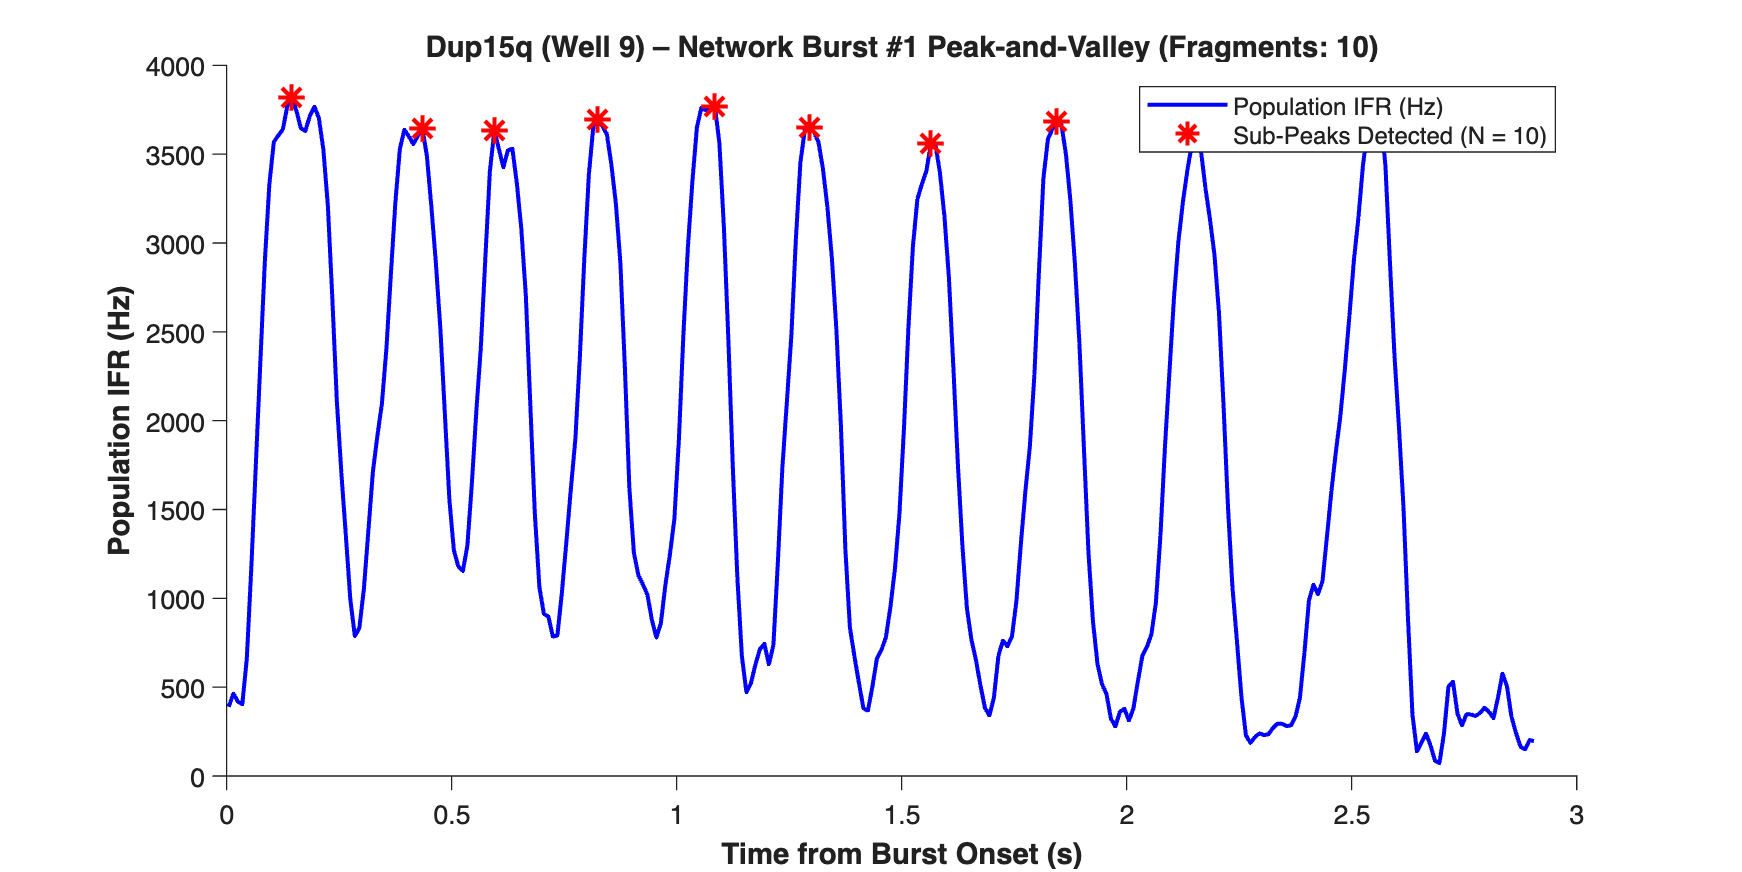


% Parameters for peak detection
binSizeSecPeak   = 0.010;   % 10 ms bin resolution for fine-grained burst profile
smoothWindowPeak = 5;       % Gaussian smoothing window span

% Retrieve selected well from Section 4 or fallback to first Pathological well
if exist('pathoIdx', 'var') && ~isempty(patho.bursts{pathoIdx})
    selectedWellSpikes = patho.spikes{pathoIdx};
    selectedBurstWin   = patho.bursts{pathoIdx}(1, :); % First burst [startSample, endSample]
    wellName           = patho.wells{pathoIdx};
    groupName          = patho.name;
else
    selectedWellSpikes = patho.spikes{1};
    selectedBurstWin   = patho.bursts{1}(1, :);
    wellName           = patho.wells{1};
    groupName          = patho.name;
end

% Execute Peak-and-Valley visualization on single burst
if ~isempty(selectedBurstWin)
    plotSingleBurstPeakValleyDetail(selectedWellSpikes, selectedBurstWin, fs, ...
        binSizeSecPeak, smoothWindowPeak, ...
        sprintf('%s (%s) – Network Burst #1 Peak-and-Valley', groupName, wellName));
end

## 6. QUANTITATIVE BIOMARKER DISCOVERY: BURST FRAGMENTATION (PEAK-AND-VALLEY)

Applies the IFR Peak-and-Valley detection algorithm across ALL network bursts for each well in both conditions (Control vs Dup15q). Computes the average fragments per burst for each well and evaluates statistical separation using a two-sided Mann-Whitney U test.

fprintf('Computing group-level Peak-and-Valley Burst Fragmentation...\n');

Computing group-level Peak-and-Valley Burst Fragmentation...



% Parameters for peak detection
binSizeSecPeak   = 0.010;   % 10 ms bin resolution
smoothWindowPeak = 5;       % Gaussian smoothing window

% Extract fragments per network burst for each well in both groups
ctrl.metrics.fragmentsPerBurst  = computeGroupFragmentationPeakValley(ctrl.spikes, ctrl.bursts, fs, binSizeSecPeak, smoothWindowPeak);
patho.metrics.fragmentsPerBurst = computeGroupFragmentationPeakValley(patho.spikes, patho.bursts, fs, binSizeSecPeak, smoothWindowPeak);

% Display Quantitative Results in Console
fprintf('\n--- Burst Fragmentation Summary (Mean Fragments per NB) ---\n');


--- Burst Fragmentation Summary (Mean Fragments per NB) ---


for w = 1:length(ctrl.wells)
    fprintf('  %s (%s): %.2f fragments/burst\n', ctrl.name, ctrl.wells{w}, ctrl.metrics.fragmentsPerBurst(w));
end

  Control (Well 11): 1.08 fragments/burst
  Control (Well 17): 1.00 fragments/burst
  Control (Well 23): 1.07 fragments/burst


for w = 1:length(patho.wells)
    fprintf('  %s (%s): %.2f fragments/burst\n', patho.name, patho.wells{w}, patho.metrics.fragmentsPerBurst(w));
end

  Dup15q (Well 8): 7.55 fragments/burst
  Dup15q (Well 9): 10.83 fragments/burst
  Dup15q (Well 14): 11.76 fragments/burst


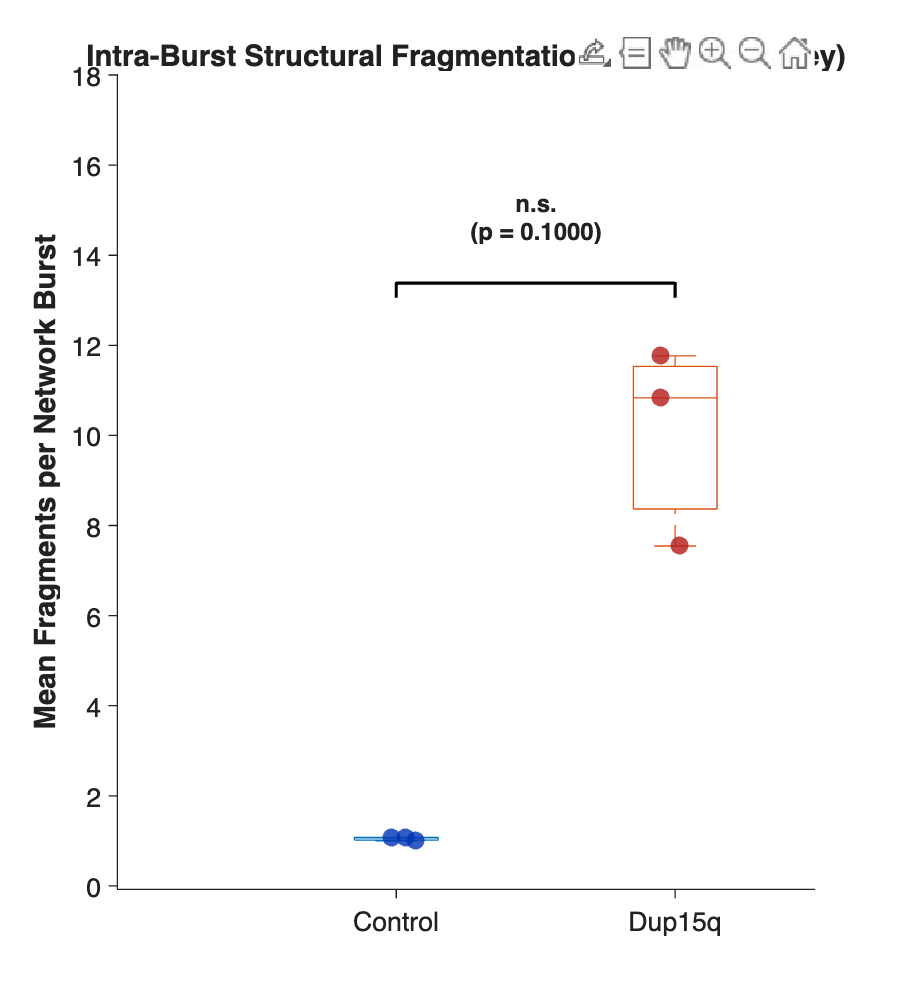

% Plot Biomarker Comparison Boxplot
figure('Name', 'Biomarker Discovery: Burst Fragmentation', 'Color', 'w', 'Position', [300, 300, 450, 500]);
compareAndPlot(ctrl.metrics.fragmentsPerBurst, patho.metrics.fragmentsPerBurst, ...
    'Mean Fragments per Network Burst', ctrl.name, patho.name);

title('Intra-Burst Structural Fragmentation (Peak-and-Valley)', 'FontSize', 11, 'FontWeight', 'bold');

#### Interpretation:

Quantitative analysis of network burst micro-architecture using Peak-and-Valley IFR detection reveals a striking separation between Control and Dup15q networks. Healthy control cultures generate highly cohesive network bursts averaging approximately 1 fragment per event. In contrast, Dup15q cultures display structural instability, stuttering into 7.5 to 12 fragments per network burst.

From a statistical standpoint, the two-sided Mann-Whitney U test yields p=0.1000. With N=3 wells per group, p=0.1000 represents the **absolute minimum achievable p-value** due to permutation limits with 20 possible rank arrangements, yielding pmin= 2/20= 0.100).

Because every Dup15q well ranks strictly above every Control well, the fragmentation metric achieves **maximum possible rank separation** for this sample size, validating intra-burst fragmentation as a robust biomarker for Dup15q phenotypic screening where standard macroscopic metrics failed to discriminate the pathological phenotype.

## Function for SubPlots

function plotSubplotRasterIFR(spikesWell, burstsWell, fs, plotTitle, lineColor, binSizeSec, smoothWindow)
    allSpikes = vertcat(spikesWell{:}) / fs;
    if isempty(allSpikes), warning('Selected well contains no spikes.'); return; end
    
    maxTime = max(allSpikes);
    edges = 0:binSizeSec:maxTime;
    timeCenters = edges(1:end-1) + binSizeSec/2;
    counts = histcounts(allSpikes, edges);
    
    ifr = counts / binSizeSec;
    ifr_smooth = smoothdata(ifr, 'gaussian', smoothWindow); 
    
    hold on;
    
    % -- LEFT Y-AXIS: RASTER PLOT --
    yyaxis left; 
    for ch = 1:length(spikesWell)
        spSec = spikesWell{ch} / fs;
        if ~isempty(spSec)
            plot(spSec, ch * ones(size(spSec)), 'k.', 'MarkerSize', 5);
        end
    end
    ylim([0, length(spikesWell) + 1]);
    ylabel('Electrode', 'Color', 'k', 'FontWeight', 'bold');
    set(gca, 'YColor', 'k', 'YDir', 'reverse');
    
    % -- RIGHT Y-AXIS: IFR LINE --
    yyaxis right; 
    plot(timeCenters, ifr_smooth, '-', 'Color', lineColor, 'LineWidth', 1.5);
    ylabel('Population IFR (Hz)', 'Color', lineColor, 'FontWeight', 'bold');
    set(gca, 'YColor', lineColor);
    
    % -- HIGHLIGHT NETWORK BURSTS --
    if ~isempty(burstsWell)
        burstsSec = burstsWell / fs;
        yL = ylim;
        for b = 1:size(burstsSec, 1)
            patch([burstsSec(b,1) burstsSec(b,2) burstsSec(b,2) burstsSec(b,1)], ...
                  [yL(1) yL(1) yL(2) yL(2)], 'y', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
        end
        % Auto-zoom to a 10-second window centered around the FIRST burst
        firstBurstStart = burstsSec(1,1);
        xlim([max(0, firstBurstStart - 2), firstBurstStart + 8]);
    else
        xlim([0, min(10, maxTime)]);
    end
    
    xlabel('Time (s)', 'FontWeight', 'bold');
    title(plotTitle, 'FontSize', 11, 'FontWeight', 'bold');
    box off; set(gca, 'TickDir', 'out');
end


## Local Functions

function [spikes, bursts] = loadGroupData(group, fs)
    % Dynamically loads peak_trains and NetBurst matrices for the group
    nWells = length(group.wells);
    spikes = cell(nWells, 1);
    bursts = cell(nWells, 1);
    
    for w = 1:nWells
        % 1. Load Spikes (peak_train)
        wellNum = extractAfter(group.wells{w}, 'Well ');
        searchStr = sprintf('well_%s_PeakDetectionMAT*', wellNum);
        peakDir = dir(fullfile(group.path, group.wells{w}, searchStr));
        
        if ~isempty(peakDir)
            matFiles = dir(fullfile(group.path, group.wells{w}, peakDir(1).name, group.ptrain{w}, '*.mat'));
            elecSamples = cell(length(matFiles), 1);
            for ch = 1:length(matFiles)
                data = load(fullfile(matFiles(ch).folder, matFiles(ch).name));
                if isfield(data, 'peak_train')
                    elecSamples{ch} = find(data.peak_train);
                end
            end
            spikes{w} = elecSamples;
        end
        
        % 2. Load Bursts (NetBurst)
        bName = sprintf('well_%s_Well%s_NetworkBurstDetection.mat', wellNum, wellNum);
        bPath = fullfile(group.path, group.wells{w}, 'Well_BurstDetectionMAT', 'Well_NetworkBurstDetectionFiles', bName);
        if exist(bPath, 'file')
            data = load(bPath);
            if isfield(data, 'NetBurst'), bursts{w} = data.NetBurst;
            elseif isfield(data, 'netBursts'), bursts{w} = data.netBursts; 
            end
        end
    end
end


function printActiveElectrodeSummary(group)
    % Display active and recorded electrode counts for each well.
    fprintf('\n%s\n', group.name);
    for w = 1:numel(group.wells)
        nActive = group.metrics.nActiveElectrodes(w);
        nTotal = group.metrics.nElectrodes(w);
        if isnan(nActive)
            fprintf('  %s: data not available\n', group.wells{w});
        else
            fprintf('  %s: %d/%d active electrodes\n', ...
                group.wells{w}, nActive, nTotal);
        end
    end
end

function res = extractBiomarkers(spikes, bursts, fs, recDur, minActiveElectrodeFR)
    % Extract well-level biomarkers from electrode spike trains and network bursts.
    % MFR is averaged across active electrodes only; burst-level population
    % firing rate pools spikes across all recorded electrodes.
    nWells = length(spikes);
    
    % Initialize outputs with NaNs to handle empty recordings safely
    res.mfr = nan(nWells, 1);
    res.nbr = nan(nWells, 1);
    res.burstDur = nan(nWells, 1);
    res.spikesPerBurst = nan(nWells, 1);
    res.spikesInNetworkBurstsPct = nan(nWells, 1);
    res.intraFR = nan(nWells, 1);
    res.nElectrodes = nan(nWells, 1);
    res.nActiveElectrodes = nan(nWells, 1);
    
    for w = 1:nWells
        wellSpikes = spikes{w};
        nb = bursts{w};
        
        if isempty(wellSpikes), continue; end
        
        % 1. Identify active electrodes and calculate the well-level MFR.
        nChannels = numel(wellSpikes);
        electrodeSpikeCounts = cellfun(@numel, wellSpikes);
        electrodeFR = electrodeSpikeCounts / recDur;
        activeElectrodeMask = electrodeFR >= minActiveElectrodeFR;

        res.nElectrodes(w) = nChannels;
        res.nActiveElectrodes(w) = sum(activeElectrodeMask);

        % Mean Firing Rate: average only across electrodes meeting the
        % predefined activity threshold.
        if any(activeElectrodeMask)
            res.mfr(w) = mean(electrodeFR(activeElectrodeMask));
        end

        % Keep all recorded electrodes for population-level burst metrics.
        totalSpikesWell = sum(electrodeSpikeCounts);
        if isempty(nb), continue; end
        
        % 2. NBR & Duration
        nBursts = size(nb, 1);
        res.nbr(w) = nBursts / recDur;
        durationsSec = (nb(:, 2) - nb(:, 1)) / fs;
        res.burstDur(w) = mean(durationsSec);
        
        % 3. Intra-Burst Metrics
        spikesInThisWellNBs = 0;
        burstFRs = zeros(nBursts, 1);
        spikesPerB = zeros(nBursts, 1);
        
        for b = 1:nBursts
            t0 = nb(b, 1);
            t1 = nb(b, 2);
            
            % Count spikes across all recorded electrodes within this burst.
            % This preserves a population-level firing rate, not an average
            % across active electrodes.
            spkCount = 0;
            for ch = 1:nChannels
                sp = wellSpikes{ch};
                spkCount = spkCount + sum(sp >= t0 & sp <= t1);
            end
            
            spikesInThisWellNBs = spikesInThisWellNBs + spkCount;
            spikesPerB(b) = spkCount;
            burstFRs(b) = spkCount / durationsSec(b);
        end
        
        res.spikesPerBurst(w) = mean(spikesPerB);
        res.intraFR(w) = mean(burstFRs);
        % Percentage of all detected spikes that occur during network bursts.
        % This describes burst-associated activity, not synchrony directly.
        res.spikesInNetworkBurstsPct(w) = (spikesInThisWellNBs / totalSpikesWell) * 100;
    end
end

function compareAndPlot(ctrlData, pathoData, yLabelStr, ctrlName, pathoName)
    % Rimuove i valori mancanti e valuta i gruppi indipendenti con il test di Mann-Whitney (ranksum)
    ctrlClean = ctrlData(~isnan(ctrlData));
    pathoClean = pathoData(~isnan(pathoData));
    
    if isempty(ctrlClean) || isempty(pathoClean)
        return; 
    end
    
    % Test statistico non parametrico (Mann-Whitney U)
    pVal = ranksum(ctrlClean, pathoClean);
    
    groupData = [ctrlClean; pathoClean];
    groupLabels = [ones(size(ctrlClean)); 2 * ones(size(pathoClean))];
    
    hold on;
    
    % 1. Plot dei Boxplot
    boxplot(groupData, groupLabels, 'Labels', {ctrlName, pathoName}, ...
        'Colors', [0 0.4470 0.7410; 0.8500 0.3250 0.0980], 'Symbol', ''); % Symbol '' rimuove gli outlier di default
    
    % 2. Sovrapposizione dei punti singoli per ogni pozzetto (Scatter con Jitter)
    rng(42); % Seed fisso per rendere il jitter riproducibile
    jitterCtrl  = 1 + (rand(size(ctrlClean)) - 0.5) * 0.15;
    jitterPatho = 2 + (rand(size(pathoClean)) - 0.5) * 0.15;
    
    scatter(jitterCtrl, ctrlClean, 45, [0 0.2 0.7], 'filled', ...
        'MarkerFaceAlpha', 0.8, 'DisplayName', 'Control Wells');
    scatter(jitterPatho, pathoClean, 45, [0.7 0.1 0.1], 'filled', ...
        'MarkerFaceAlpha', 0.8, 'DisplayName', 'Dup15q Wells');
    
    ylabel(yLabelStr, 'FontWeight', 'bold');
    
    % 3. Formattazione delle stelle di significatività
    if pVal < 0.001, sigStr = '***';
    elseif pVal < 0.01, sigStr = '**';
    elseif pVal < 0.05, sigStr = '*';
    else, sigStr = 'n.s.';
    end
    
    % 4. Calcolo dinamico della posizione della barra di significatività
    yMax = max(groupData);
    yMin = min(groupData);
    yRange = yMax - yMin;
    if yRange == 0, yRange = max(yMax, 1) * 0.1; end
    
    yLine = yMax + yRange * 0.15;
    yText = yLine + yRange * 0.08;
    
    % Disegna la barra orizzontale con i muretti verticali
    plot([1, 1, 2, 2], [yLine - yRange*0.03, yLine, yLine, yLine - yRange*0.03], 'k-', 'LineWidth', 1.2);
    
    % Aggiunge il testo con asterischi e p-value sopra la barra
    text(1.5, yText, sprintf('%s\n(p = %.4f)', sigStr, pVal), ...
        'HorizontalAlignment', 'center','VerticalAlignment', 'bottom', 'FontSize', 9, 'FontWeight', 'bold');
    
    % Regola i limiti dell'asse Y per evitare che la barra venga tagliata
    ylim([yMin - yRange*0.1, yText + yRange*0.35]);
    
    box off;
    set(gca, 'TickDir', 'out', 'LineWidth', 1);
    hold off;
end

function plotBurstProfile(spikes, bursts, fs, binSizeMs, windowMs, plotColor)
    % Aligns all network bursts to t=0 and computes the average IFR profile
    
    binSec = binSizeMs / 1000;
    winSec = windowMs / 1000;
    edges = 0:binSec:winSec;
    timeCenters = (edges(1:end-1) + binSec/2) * 1000; % Convert to ms for x-axis
    
    nWells = length(spikes);
    
    for w = 1:nWells
        wellSpikes = spikes{w};
        nb = bursts{w};
        
        if isempty(wellSpikes) || isempty(nb), continue; end
        
        nBursts = size(nb, 1);
        ifrAllBursts = zeros(nBursts, length(timeCenters));
        
        for b = 1:nBursts
            t0 = nb(b, 1);
            t1 = nb(b, 2);
            
            % Pool all spikes in this burst
            bSpikes = [];
            for ch = 1:length(wellSpikes)
                sp = wellSpikes{ch};
                bSpikes = [bSpikes; sp(sp >= t0 & sp <= t1)];
            end
            
            % Align spikes so burst onset is exactly at t = 0
            bSpikes = bSpikes - t0; 
            bSpikesSec = bSpikes / fs;
            
            % Count spikes in each time bin and convert to Hz
            counts = histcounts(bSpikesSec, edges);
            ifrAllBursts(b, :) = counts / binSec;
        end
        
        % Average across all bursts for THIS well
        meanIfrWell = mean(ifrAllBursts, 1);
        
        % Plot this well's profile as a line (alpha blended for aesthetics)
        plot(timeCenters, meanIfrWell, 'Color', [plotColor, 0.6], 'LineWidth', 1.5, ...
             'DisplayName', sprintf('Well %d', w));
    end
    
    % Optional: You can also compute and plot the grand mean across all wells here
    % if you want a single thick line summarizing the whole group.
end


function plotSingleBurstPeakValleyDetail(spikesWell, nbWindow, fs, binSizeSec, smoothWindow, plotTitle)
    % Plots high-resolution population IFR for a single burst and identifies 
    % intra-burst sub-peaks (burstlets) using findpeaks with prominence thresholding.

    t0 = nbWindow(1);
    t1 = nbWindow(2);

    % 1. Pool all spikes occurring within this network burst window
    burstSpikes = [];
    for ch = 1:length(spikesWell)
        sp = spikesWell{ch};
        burstSpikes = [burstSpikes; sp(sp >= t0 & sp <= t1)];
    end

    if length(burstSpikes) < 3
        warning('Insufficient spikes in the selected network burst to perform peak detection.');
        return;
    end

    % 2. Calculate binned population IFR and Gaussian smoothed envelope
    burstDurSec  = (t1 - t0) / fs;
    edges        = 0:binSizeSec:(burstDurSec + binSizeSec);
    spikesRelSec = (sort(burstSpikes) - t0) / fs;

    counts      = histcounts(spikesRelSec, edges);
    ifr         = counts / binSizeSec;
    ifrSmooth   = smoothdata(ifr, 'gaussian', smoothWindow);
    timeCenters = edges(1:end-1) + binSizeSec/2;

    % 3. Detect sub-burst peaks using findpeaks
    minProminence = 0.15 * max(ifrSmooth); % Sub-peak must rise by at least 15% of max IFR
    minDistance   = 0.030;                 % Minimum 30 ms distance between sub-peaks

    [pks, locs] = findpeaks(ifrSmooth, timeCenters, ...
        'MinPeakProminence', minProminence, ...
        'MinPeakDistance', minDistance);

    nFragments = max(1, length(pks));

    % 4. Render Figure
    figure('Name', plotTitle, 'Color', 'w', 'Position', [200, 200, 900, 450]);
    plot(timeCenters, ifrSmooth, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Population IFR (Hz)'); 
    hold on;

    % Mark detected sub-peaks with red asterisks (*)
    if ~isempty(pks)
        plot(locs, pks, 'r*', 'MarkerSize', 10, 'LineWidth', 1.5, ...
             'DisplayName', sprintf('Sub-Peaks Detected (N = %d)', nFragments));
    end

    xlabel('Time from Burst Onset (s)', 'FontWeight', 'bold');
    ylabel('Population IFR (Hz)', 'FontWeight', 'bold');
    title(sprintf('%s (Fragments: %d)', plotTitle, nFragments), ...
          'FontSize', 11, 'FontWeight', 'bold');
    legend('Location', 'northeast');
    box off; set(gca, 'TickDir', 'out');
end

function fragPerWell = computeGroupFragmentationPeakValley(spikesGroup, burstsGroup, fs, binSizeSec, smoothWindow)
    % Calculates the average number of IFR sub-peaks (burstlets) per network burst
    % across all bursts for each well in a group using findpeaks.
    
    nWells = length(spikesGroup);
    fragPerWell = nan(nWells, 1);
    
    for w = 1:nWells
        wellSpikes = spikesGroup{w};
        nb = burstsGroup{w};
        
        if isempty(wellSpikes) || isempty(nb), continue; end
        
        nBursts = size(nb, 1);
        fragments = zeros(nBursts, 1);
        
        for b = 1:nBursts
            t0 = nb(b, 1);
            t1 = nb(b, 2);
            
            % Pool spikes occurring inside this network burst
            burstSpikes = [];
            for ch = 1:length(wellSpikes)
                sp = wellSpikes{ch};
                burstSpikes = [burstSpikes; sp(sp >= t0 & sp <= t1)];
            end
            
            if length(burstSpikes) < 3
                fragments(b) = 1;
                continue;
            end
            
            % Binned IFR and Gaussian smoothing
            burstDurSec  = (t1 - t0) / fs;
            edges        = 0:binSizeSec:(burstDurSec + binSizeSec);
            spikesRelSec = (sort(burstSpikes) - t0) / fs;
            
            counts    = histcounts(spikesRelSec, edges);
            ifr       = counts / binSizeSec;
            ifrSmooth = smoothdata(ifr, 'gaussian', smoothWindow);
            timeCenters = edges(1:end-1) + binSizeSec/2;
            
            % Peak detection on IFR envelope
            minProminence = 0.15 * max(ifrSmooth); % 15% prominence threshold
            minDistance   = 0.030;                 % 30 ms minimum distance between sub-peaks
            
            pks = findpeaks(ifrSmooth, timeCenters, ...
                'MinPeakProminence', minProminence, ...
                'MinPeakDistance', minDistance);
            
            fragments(b) = max(1, length(pks));
        end
        
        fragPerWell(w) = mean(fragments);
    end
end